## Temperature data Torhout

api = "https://archive-api.open-meteo.com/v1/archive?latitude=51.07&longitude=3.10&start_date=2022-02-08&end_date=2023-02-07&daily=temperature_2m_max,temperature_2m_min,temperature_2m_mean&timezone=Europe%2FBerlin";
s = webread(api);

max_temperature = s.daily.temperature_2m_max; % max temp of every day of the year
mean_temperature = s.daily.temperature_2m_mean; % mean temp of every day of the year
min_temperature = s.daily.temperature_2m_min; % min temp of every day of the year

mean_mean = mean(mean_temperature); % mean of the mean temp of the year
mean_max = mean(max_temperature); % mean of the max temp of the year
mean_min = mean(min_temperature); % mean of the min temp o fthe year

## Heat loss building

U_glas = 1.7;
U_deur = 1.7;
U_muur = 1;
height = 4; % estimate of the height indoor

omtrek_muur = 52.44;
omtrek_raam = 12;
omtrek_deur = 5.94;

temp_binnen = 22.5; % estimate indoor temp.

% calculate mean power to heat the building every day
Q=height*(temp_binnen - mean_temperature)*(omtrek_muur*U_muur + omtrek_raam*U_glas+omtrek_deur*U_deur);
Q=height*(temp_binnen - mean_mean)*(omtrek_muur*U_muur + omtrek_raam*U_glas+omtrek_deur*U_deur)

Q = 3.4282e+03

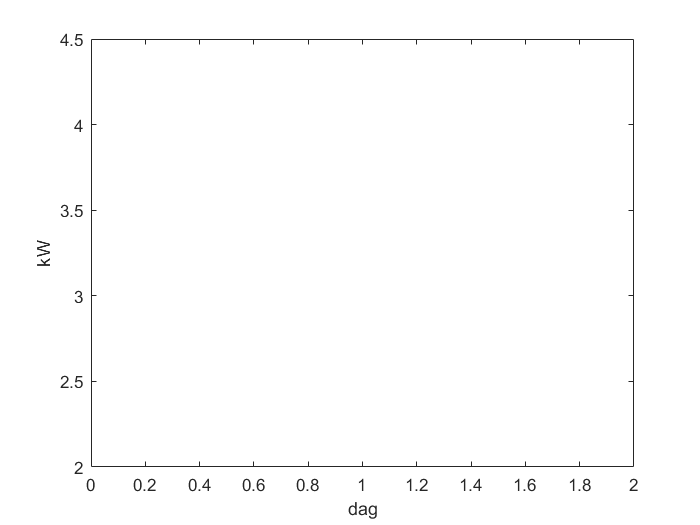


% plot the data
plot(Q*10^(-3))
xlabel("dag")
ylabel("kW");

## Verbruik facturen

gas = 165997;   %[kWh]
elek_dag = 50148;   %[kWh]
elek_nacht = 24952; %[kWh]

verbruik_totaal = gas+elek_dag+elek_nacht;

## Verbruik droge sauna

vermogen_verwarmer = 7.5*10^3; %[W]

temp_sauna = 90; %estimate indoor temp of sauna %[°C]
dT_binnen = temp_sauna-temp_binnen;
dT_buiten = temp_sauna-mean_min;

Oppervlaktes

hoogte = 2.5;
% muur 1 (zie plan)
A_deur_muur_1 = 1*2; %[m]
A_muur_1 = (4.78)*hoogte - A_deur_muur_1;

% muur 2
A_muur_2 = 2.9*hoogte;

% muur 3
A_ramen_muur_3 = 2*0.2;
A_muur_3 = (4.78)*hoogte - A_ramen_muur_3;

% muur 4
A_raam_muur_4 = 1.2*0.2;
A_muur_4 = 2.9*hoogte-A_raam_muur_4;

% plafond
A_plafond = 2.9*4.78;

Thermische weerstanden

% lambda waardes
l_isol = 0.04; %[W/m*K]
l_hout = 0.15;
l_enkel_glas = 0.8;
l_gips = 0.15;

% Diktes
d_isol = 0.06; %[m]
d_sauna_hout = 0.026;
d_binnenmuur = 0.15;
d_plafond_hout = 0.04;
d_enkel_glas = 0.004;
d_binnenmuur_dun = 0.10;

% R waardes
R_se = 1/25;
R_si = 1/10;
R_saunamuur = d_isol/l_isol + d_sauna_hout/l_hout;
R_plafond = d_plafond_hout/l_hout + d_isol/l_isol;
R_enkel_glas = d_enkel_glas/l_enkel_glas;

% U waardes
U_saunamuur = 1/R_saunamuur;
U_plafond = 1/(R_si + R_plafond + R_si);
% U_enkel_glas = 1/R_enkel_glas;
U_enkel_glas = 5.8;
U_dubbel_glas= 1.7; % Gegeven astralite
U_binnenmuur = 0.30; % Gegeven internet
U_buitenmuur = 1; % Gegeven EPB 2006

U_muur_1 = 1/(R_si + R_saunamuur + R_si);
U_muur_2 = 1/(R_saunamuur + 1/U_binnenmuur);
U_muur_3 = U_muur_2;
U_muur_4 = 1/(R_saunamuur + 1/U_buitenmuur);



% Heat loss
Q_muur_1 = dT_binnen*(A_muur_1 * U_muur_1 + A_deur_muur_1*U_enkel_glas);
Q_muur_2 = A_muur_2 * U_muur_2 * dT_binnen;
Q_muur_3 = (A_muur_3 * U_muur_3+A_ramen_muur_3*U_enkel_glas) * dT_binnen;
Q_muur_4 = dT_buiten*(A_raam_muur_4*U_dubbel_glas+A_muur_4*U_muur_4);
Q_plafond = dT_binnen*(A_plafond*U_plafond);
Q_tot = Q_muur_1 +Q_muur_2 +Q_muur_3 + Q_plafond +Q_muur_4

Q_tot = 2.2728e+03

## Opstarte droge sauna

Constanten

temp_begin = 22; %[C]
volume = (4.78)*(2.90)*hoogte %[m^3];

volume = 34.6550

rho = 1.23; %[kg/m^3]
cp = 1005; %[J/kg K]

n_50 = 0.6;
H_vent = 0.34*n_50*volume; %[W/K]
AU_totaal_binnen = (A_muur_1 * U_muur_1 + A_deur_muur_1*U_enkel_glas)+A_muur_2 * U_muur_2 +(A_muur_3 * U_muur_3+A_ramen_muur_3*U_enkel_glas)+(A_plafond*U_plafond);
AU_totaal_buiten = (A_raam_muur_4*U_dubbel_glas+A_muur_4*U_muur_4);

Differentiaal vergelijking

syms T(t)
cond = T(0) == temp_begin+273;
ode = diff(T,t)*rho*volume*cp==vermogen_verwarmer - AU_totaal_buiten*(T-(mean_min+273))-AU_totaal_binnen*(T-(temp_binnen+273)) - H_vent*(T-(temp_binnen+273))  ;
TSol(t) = dsolve(ode, cond);
vpa(TSol(0)-273)

$$ans = 22.0$$

T_inverse = finverse(TSol);
vpa(T_inverse(90+273))/60

$$ans = 8.0760620778328802672956913072664$$

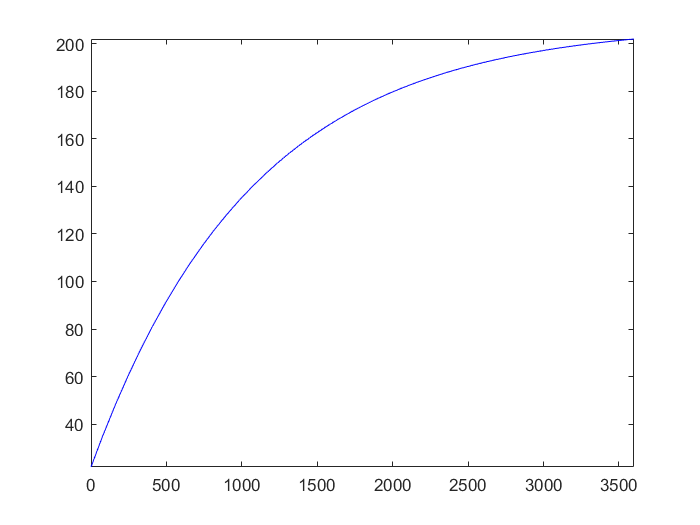

fplot(@(t) TSol(t)-273,[0 3600],'b')

### Verbruik finse sauna

vermogen_verwarmer_2 = 5*10^3;

temp_sauna_2 = 70;
dT_binnen_2 = temp_sauna_2 - temp_binnen;
dT_buiten_2 = temp_sauna_2 - mean_min;

Oppervlaktes

% muur 5
A_deur_muur_5 = 1*2;
A_muur_5 = hoogte * 2.586;

% muur 6
A_muur_6 = hoogte * 2.483;

% muur 7
A_muur_7 = A_muur_5;

% muur 8
A_muur_8 = A_muur_6;

% plafond
A_plafond_2 = 2.586 * 2.483;


Thermische weerstanden

% U-waarden
U_muur_5 = U_muur_1;
U_muur_6 = 1/(R_saunamuur + R_si + d_binnenmuur_dun/l_gips + R_si);
U_muur_7 = U_muur_4;
U_muur_8 = U_muur_6;

Q_muur_5 = A_muur_5*U_muur_5*dT_binnen_2 + A_deur_muur_5*U_enkel_glas*dT_binnen_2;
Q_muur_6 = A_muur_6*U_muur_6*dT_binnen_2;
Q_muur_7 = A_muur_7*U_muur_7*dT_buiten_2;
Q_muur_8 = A_muur_8*U_muur_8*dT_binnen_2;
Q_plafond = A_plafond_2*U_plafond*dT_binnen_2;
Q_tot = Q_muur_5 + Q_muur_6 + Q_muur_7 + Q_muur_8 + Q_plafond

Q_tot = 1.1022e+03

## Opstarte finse sauna

Constanten

temp_begin_2 = 22; %[C]
volume_2 = 2.586*2.483*hoogte; %[m^3]
H_vent_2 = 0.34*n_50*volume_2;

AU_totaal_binnen_2 = (A_muur_5 * U_muur_5 + A_deur_muur_5*U_enkel_glas) + A_muur_6 * U_muur_6 + A_muur_8*U_muur_8 + A_plafond*U_plafond;
AU_totaal_buiten_2 = A_muur_7*U_muur_7;

Differentiaal vergelijking

syms T(t)
cond = T(0) == temp_begin_2+273;
ode = diff(T,t)*rho*volume_2*cp==vermogen_verwarmer_2 - AU_totaal_buiten_2*(T-(mean_min+273))-AU_totaal_binnen_2*(T-(temp_binnen+273)) - H_vent_2*(T-(temp_binnen+273))  ;
TSol(t) = dsolve(ode, cond);
vpa(TSol(0)-273)

$$ans = 22.0$$

T_inverse = finverse(TSol);
vpa(T_inverse(90+273))/60

$$ans = 5.9750758881871206384950947874552$$

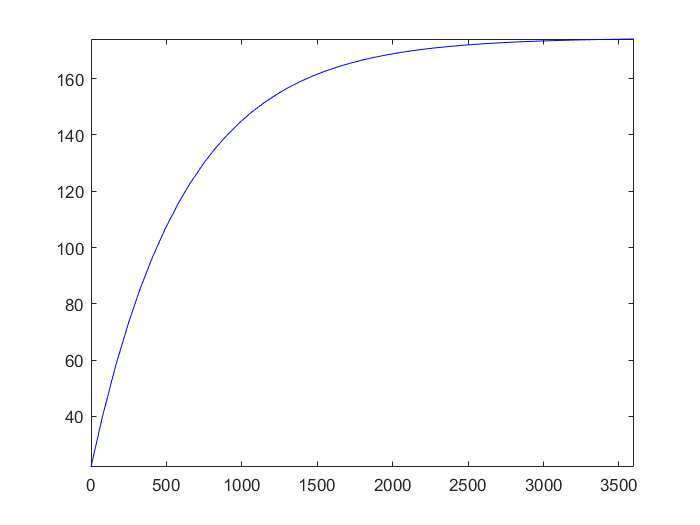

fplot(@(t) TSol(t)-273,[0 3600],'b')